# Data Preprocessing dan Data Understanding

data = readtable("D:\File\Bisa.AI\Automobile_data.csv");

data(1:5,:)

ans = 5×26 table
    symboling    normalized_losses        make         fuel_type    aspiration    num_of_doors     body_style      drive_wheels    engine_location    wheel_base    length    width    height    curb_weight    engine_type    num_of_cylinders    engine_size    fuel_system     bore     stroke    compression_ratio    horsepower    peak_rpm    city_mpg    highway_mpg     price 
    _________    _________________    _____________    _________    __________   

Ganti "?" menjadi "NaN"

data = standardizeMissing(data,'?')

data = 205×26 table
    symboling    normalized_losses        make         fuel_type    aspiration    num_of_doors     body_style      drive_wheels    engine_location    wheel_base    length    width    height    curb_weight    engine_type    num_of_cylinders    engine_size    fuel_system     bore     stroke    compression_ratio    horsepower    peak_rpm    city_mpg    highway_mpg     price 
    _________    _________________    _____________    _________    __________

Define Numerical and Categorical Data

numerik = {'symboling','normalized_losses','wheel_base','length','width','height','curb_weight','engine_size','bore','stroke','compression_ratio','horsepower','peak_rpm','city_mpg','highway_mpg','price'};
cat = {'make','fuel_type','aspiration','num_of_doors','body_style','drive_wheels','engine_location','engine_type','num_of_cylinders','fuel_system'};

Convert numerik -> double; categorical -> string

for i=1:numel(numerik)
    if class(data{:,numerik{i}}) == "cell"
        data.(numerik{i}) = str2double(data{:,numerik{i}});
    end
end

Handling Missing Value

data = rmmissing(data) % delete rows data yang kosong

data = 159×26 table
    symboling    normalized_losses       make        fuel_type    aspiration    num_of_doors    body_style     drive_wheels    engine_location    wheel_base    length    width    height    curb_weight    engine_type    num_of_cylinders    engine_size    fuel_system    bore    stroke    compression_ratio    horsepower    peak_rpm    city_mpg    highway_mpg    price
    _________    _________________    ___________    _________    __________    

%data = rmmissing(data,2,'MinNumMissing',5) % delete columns data yang kosong minim 5

% fill Numerical Data using Mean
%m_data = mean(data.normalized_losses,'omitnan'); % calculate mean without NaN
%data.normalized_losses = fillmissing(data.normalized_losses,'constant',m_data);

%fill categorical data using Modus
%modus = mode(categorical(data.num_of_doors))    %find the mode
%data.num_of_doors = fillmissing(data.num_of_doors,'constant',cellstr(modus))    %fill mode

Standarization, Normalitation etc.

%data.normalized_losses = normalize(data.normalized_losses,'range'); % normalize data to [0 1]
%data.normalized_losses = normalize(data.normalized_losses,'zscore'); % normalize data with mu = 0 and std = 1

Categorical to Numerical

%data.make = double(categorical(data.make))
%data.make = dummyvar(categorical(data.make))

Korelasi

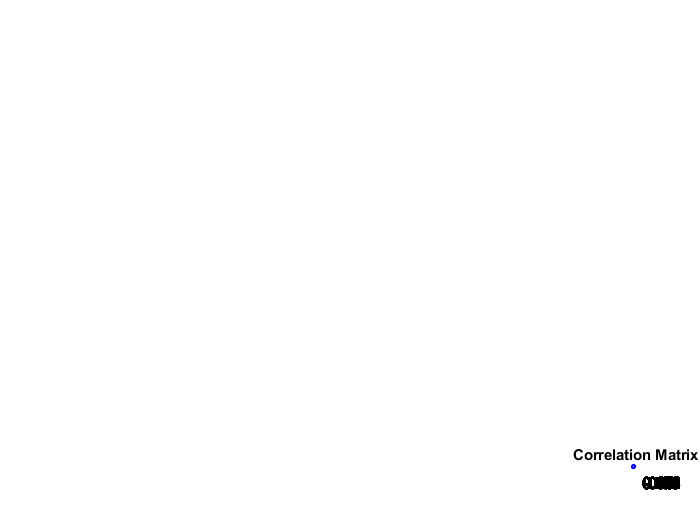

corrplot(data{:,numerik})